DirectoryName = "C:\Users\chase\Documents\22-23 Senior Project M1 Research\Summer24_Measurements\Pork_Summer24_3\Pork\";
DirectoryName2 = "C:\Users\chase\Documents\22-23 Senior Project M1 Research\Summer24_Measurements\Pork_Summer24_3\Pork+Fat\";
DirectoryName3 = "C:\Users\chase\Documents\22-23 Senior Project M1 Research\Summer24_Measurements\Pork_Summer24_3\Compressed_Pork\";
DirectoryName4 = "C:\Users\chase\Documents\22-23 Senior Project M1 Research\Summer24_Measurements\Pork_Summer24_3\Compressed_Pork+Fat\";
%paste in your csv or xlsx files here:

FileNames = [
    "PF T1.csv";
    "PF T2.csv";
    "PF T3.csv";
    "PF T4.csv";
    "PF T5.csv";
    "PF T6.csv";
    "PF T7.csv";
    "PF T8.csv";
    "PF T9.csv";
    "PF T10.csv";
    "PF T11.csv";
    "PF T12.csv";
    "PF T13.csv";
    "PF T14.csv";
    "PF T15.csv";
    "PF T16.csv";
    "PF T17.csv";
    "PF T18.csv";
    "PF T19.csv";
    "PF T20.csv";
    "PF T21.csv";
    "PF T22.csv";
    "PF T23.csv";
    "PF T24.csv";
    "PF T25.csv";
    "PF T26.csv";
    "PF T27.csv";
    "PF T28.csv";
    "PF T29.csv";
    "PF T30.csv";
    "PF T31.csv";
    "PF T32.csv";
    "PF T33.csv";
    "PF T34.csv";
    "PF T35.csv";
    "PF T36.csv";
    "PF T37.csv";
    "PF T38.csv";
    "PF T39.csv";
    "PF T40.csv";
    "PF T41.csv";
    "PF T42.csv";
    "PF T43.csv";
    "PF T44.csv";
    "PF T45.csv";
    "PF T46.csv";
    "PF T47.csv";
    "PF T48.csv";
    "PF T49.csv";
    "PF T50.csv";
    "PF T51.csv";
    "PF T52.csv";
    "PF T53.csv";
    "PF T54.csv";
    "PF T55.csv";
    "PF T56.csv";
    "PF T57.csv";
    "PF T58.csv";
    "PF T59.csv";
    "PF T60.csv";
    "PF T61.csv";
    "PF T62.csv";
    "PF T63.csv";
    "PF T64.csv";
    "PF T65.csv";
    "PF T66.csv";
    "PF T67.csv";
    "PF T68.csv";
    "PF T69.csv";
    "PF T70.csv";
    ];

FileCount = 1:70;

%Epsilon Chars
epsilon_p = char(949) + "'"

epsilon_p = "ε'"

epsilon_pp = char(949) + "''"

epsilon_pp = "ε''"

sigma_char = char(963) + " (S/m)";

figure('Position', [1, 1, 600, 200]);
t = tiledlayout(1,3,'TileSpacing','compact','Padding','compact');
xlabel(t, " (a) ", 'FontWeight', 'bold', 'FontSize', 12);
ylabel(t, 'Probability Density', "FontSize", 12);

% Span across two rows and columns
nexttile
[x, ~, ~] = plotEpsDist(DirectoryName, FileNames, FileCount);
pd = normalFit(x)

pd =   NormalDistribution

  Normal distribution
       mu = 37.6588   [33.6835, 41.634]
    sigma = 16.6719   [14.2948, 20.0047]


%xlabel(sprintf('Real Impedance\n \\bf (b) '),'interpreter','tex', 'FontSize', 11);
xlabel(epsilon_p,  'FontSize', 12);

% Last tile
nexttile
[~, y, ~] = plotEpsDist(DirectoryName, FileNames, FileCount);
pd = normalFit(y)

pd =   NormalDistribution

  Normal distribution
       mu = 26.1333   [23.4514, 28.8153]
    sigma = 11.2478   [9.64405, 13.4963]


%xlabel(sprintf('Imaginary Impedance\n \\bf (c) '),'interpreter','tex', 'FontSize', 11);
xlabel(epsilon_pp,  'FontSize', 12);
%legend('S11', 'Normal Fit', 'Location', 'northeastoutside');

nexttile
[~, ~, z] = plotEpsDist(DirectoryName, FileNames, FileCount);
pd = normalFit(z)

pd =   NormalDistribution

  Normal distribution
       mu = 0.629509   [0.564906, 0.694113]
    sigma = 0.270941   [0.232309, 0.325103]


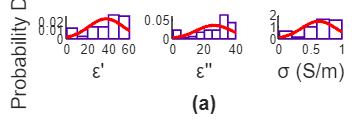

%xlabel(sprintf('Imaginary Impedance\n \\bf (c) '),'interpreter','tex', 'FontSize', 11);
xlabel(sigma_char,  'FontSize', 12);

%legend('S11', 'Normal Fit', 'Location', 'northeastoutside');


%---------------------------------

figure('Position', [1, 1, 600, 180]);
t = tiledlayout(1,3,'TileSpacing','compact','Padding','compact');
% xlabel(t, " (b) ", 'FontWeight', 'bold', 'FontSize', 12);
ylabel(t, 'Probability Density', "FontSize", 12);

% Span across two rows and columns
nexttile
[x, ~, ~] = plotEpsDist(DirectoryName2, FileNames, FileCount);
pd = normalFit(x)

pd =   NormalDistribution

  Normal distribution
       mu =  5.9479   [4.88197, 7.01384]
    sigma = 4.47043   [3.83303, 5.3641]


%xlabel(sprintf('Real Impedance\n \\bf (b) '),'interpreter','tex', 'FontSize', 11);
xlabel(epsilon_p,  'FontSize', 12);
xlim([0 25]);

% Last tile
nexttile
[~, y, ~] = plotEpsDist(DirectoryName2, FileNames, FileCount);
pd = normalFit(y)

pd =   NormalDistribution

  Normal distribution
       mu = 2.36056   [1.80455, 2.91657]
    sigma = 2.33186   [1.99938, 2.79801]


%xlabel(sprintf('Imaginary Impedance\n \\bf (c) '),'interpreter','tex', 'FontSize', 11);
xlabel(epsilon_pp,  'FontSize', 12);
%legend('S11', 'Normal Fit', 'Location', 'northeastoutside');
xlim([0 12]);

nexttile
[~, ~, z] = plotEpsDist(DirectoryName2, FileNames, FileCount);
pd = normalFit(z)

pd =   NormalDistribution

  Normal distribution
       mu =  0.056862   [0.0434686, 0.0702554]
    sigma = 0.0561707   [0.0481617, 0.0673995]


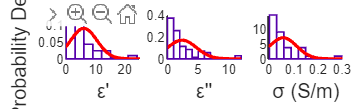

%xlabel(sprintf('Imaginary Impedance\n \\bf (c) '),'interpreter','tex', 'FontSize', 11);
xlabel(sigma_char,  'FontSize', 12);

%legend('S11', 'Normal Fit', 'Location', 'northeastoutside');

%---------------------------------

figure('Position', [1, 1, 600, 200]);
t = tiledlayout(1,3,'TileSpacing','compact','Padding','compact');
xlabel(t, " (c) ", 'FontWeight', 'bold', 'FontSize', 12);
ylabel(t, 'Probability Density', "FontSize", 12);

% Span across two rows and columns
nexttile
[x, ~, ~] = plotEpsDist(DirectoryName3, FileNames, FileCount);
pd = normalFit(x)

pd =   NormalDistribution

  Normal distribution
       mu =   33.05   [29.2033, 36.8966]
    sigma = 16.1325   [13.8323, 19.3575]


%xlabel(sprintf('Real Impedance\n \\bf (b) '),'interpreter','tex', 'FontSize', 11);
xlabel(epsilon_p,  'FontSize', 12);

% Last tile
nexttile
[~, y, ~] = plotEpsDist(DirectoryName3, FileNames, FileCount);
pd = normalFit(y)

pd =   NormalDistribution

  Normal distribution
       mu = 21.9494   [19.3368, 24.562]
    sigma =  10.957   [9.39471, 13.1473]


%xlabel(sprintf('Imaginary Impedance\n \\bf (c) '),'interpreter','tex', 'FontSize', 11);
xlabel(epsilon_pp,  'FontSize', 12);
%legend('S11', 'Normal Fit', 'Location', 'northeastoutside');

nexttile
[~, ~, z] = plotEpsDist(DirectoryName3, FileNames, FileCount);
pd = normalFit(z)

pd =   NormalDistribution

  Normal distribution
       mu = 0.528725   [0.465792, 0.591658]
    sigma = 0.263936   [0.226303, 0.316698]


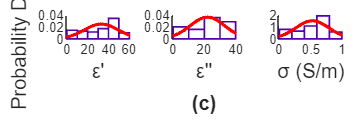

%xlabel(sprintf('Imaginary Impedance\n \\bf (c) '),'interpreter','tex', 'FontSize', 11);
xlabel(sigma_char,  'FontSize', 12);

%legend('S11', 'Normal Fit', 'Location', 'northeastoutside');

%---------------------------------

figure('Position', [1, 1, 600, 200]);
t = tiledlayout(1,3,'TileSpacing','compact','Padding','compact');
xlabel(t, " (d) ", 'FontWeight', 'bold', 'FontSize', 12);
ylabel(t, 'Probability Density', "FontSize", 12);

% Span across two rows and columns
nexttile
[x, ~, ~] = plotEpsDist(DirectoryName4, FileNames, FileCount);
pd = normalFit(x)

pd =   NormalDistribution

  Normal distribution
       mu = 3.27911   [3.03154, 3.52668]
    sigma = 1.03828   [0.890236, 1.24583]


%xlabel(sprintf('Real Impedance\n \\bf (b) '),'interpreter','tex', 'FontSize', 11);
xlabel(epsilon_p,  'FontSize', 12);

% Last tile
nexttile
[~, y, ~] = plotEpsDist(DirectoryName4, FileNames, FileCount);
pd = normalFit(y)

pd =   NormalDistribution

  Normal distribution
       mu =  1.05069   [0.942063, 1.15931]
    sigma = 0.455561   [0.390606, 0.546631]


%xlabel(sprintf('Imaginary Impedance\n \\bf (c) '),'interpreter','tex', 'FontSize', 11);
xlabel(epsilon_pp,  'FontSize', 12);
%legend('S11', 'Normal Fit', 'Location', 'northeastoutside');

nexttile
[~, ~, z] = plotEpsDist(DirectoryName4, FileNames, FileCount);
pd = normalFit(z)

pd =   NormalDistribution

  Normal distribution
       mu = 0.0253093   [0.0226928, 0.0279259]
    sigma = 0.0109737   [0.00940907, 0.0131674]


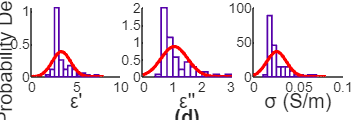

%xlabel(sprintf('Imaginary Impedance\n \\bf (c) '),'interpreter','tex', 'FontSize', 11);
xlabel(sigma_char,  'FontSize', 12);

%legend('S11', 'Normal Fit', 'Location', 'northeastoutside');

function  [x, y, z] = plotEpsDist(DirectoryName, FileNames, FileCount) %S11 dB at 433 MHz

    x = zeros(1,30); %creates (N,M) N row, M column array (matrix).
    y = zeros(1,30); %creates (N,M) N row, M column array (matrix).
    z = zeros(1,30); %creates (N,M) N row, M column array (matrix).

    for loopFiles = FileCount
        VNA_data = readmatrix(strcat(DirectoryName,FileNames(loopFiles,:)), 'Range', 14);
        Freq = 433000000;
        x(1, loopFiles) = VNA_data(134,2); %Adding data to the array made above. For smith real impedance
        y(1, loopFiles) = VNA_data(134,3); %Adding data to the array made above. For Smith imaginary impedance
        eps_o = 8.854*10^-12;
        w = 2*pi*Freq;
        z(1, loopFiles) = eps_o*w*y(1, loopFiles); %Adding data to the array made above.
    end

    % pd = fitdist(z, 'Normal');
    % ci99 = paramci(pd, 'Alpha', 0.01);
    % histfit(x);

end